# Full Demo of the Pipeline 

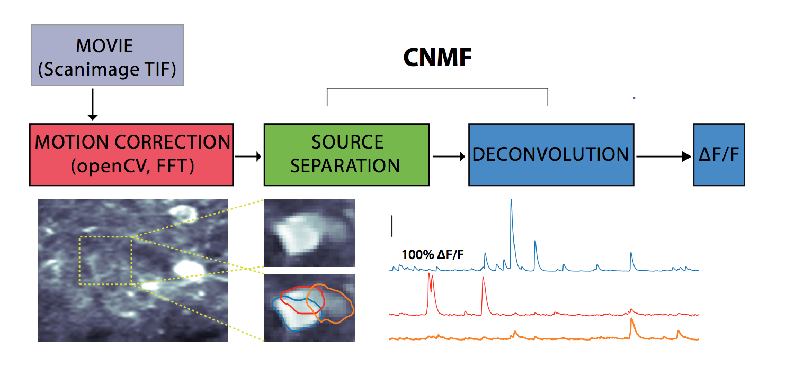

From E. Pnevmatikakis 

Free software; you can redistribute it and/or modify it under the terms of the GNU General Public License. [http://www.gnu.org/licenses/](http://www.gnu.org/licenses/)

Look at the [License](https://github.com/epnev/ca_source_extraction/license.txt) For more detail and the [ReadMe](https://github.com/epnev/ca_source_extraction/) for more information about this code.

clear;  
gcp;  % start a local cluster

# Download the file  

Data from Sue Ann Koay, Princeton Neuroscience Institute, Tank Lab.

learn more about this process and the parameters here : [Documentation](https://github.com/epnev/ca_source_extraction/documentation.pdf)   

filename = 'demoSue2x.tif';
if ~exist(filename,'file');
    url = 'https://www.dropbox.com/s/36xdfd28eone0hj/demoSue2x.tif?dl=1';
    fprintf('downloading the file...');
    outfilename = websave(filename,url);
    fprintf('done. \n');
end

## Add packages to matlab path

addpath(genpath('../../ca_source_extraction-master')); 
addpath(genpath('NoRMCorre-master'));
addpath(genpath('ca_source_extraction'));  
addpath(genpath('NoRMCorre'));

# Read file

 and determine dynamic range

Y = read_file(filename);
[d1,d2,T] = size(Y);    % dimensions of file
Y = Y - min(Y(:));      % remove negative offset

minY = quantile(Y(1:1e7),0.0005);
maxY = quantile(Y(1:1e7),1-0.0005);

## view data

figure;play_movie({Y},{'raw data'},minY,maxY);

# Perform rigid motion correction 

## Motion correction is performed in parallel on chunks taken across times. 

Create temporal chunks of the movie for parallel processing on all cores

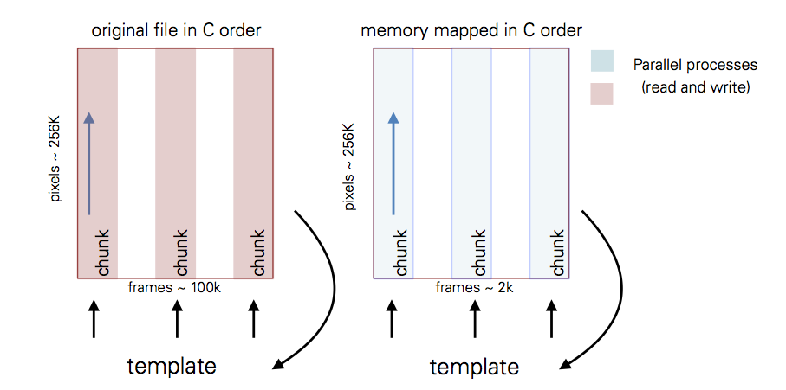

We are now left with a really shacky video. In order to correct the image movement we are using a simple rigid motion correction algorithm. 

This algorithm first creates a correlation image over time using frames from the video.

 It then tries to match each frame to this template. 

In addition the template will get updated during the matching process. Making it more precise and so does the template matching.

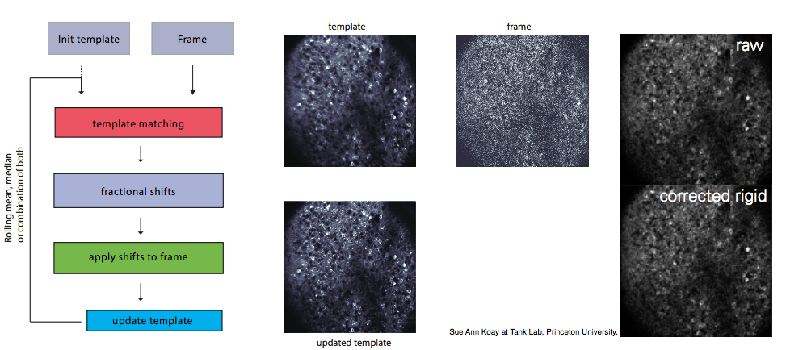

% 'd1','d2': size of FOV
% 'bin_width': how often to update the template
% 'max_shift': maximum allowed rigid shift
options_rg = NoRMCorreSetParms('d1',size(Y,1),'d2',size(Y,2),'bin_width',100,'max_shift',15);
[M_rg,shifts_rg,template_rg] = normcorre_batch(Y,options_rg); 

## view data

tsub = 5;   % downsampling factor (only for display purposes)
Y_sub = downsample_data(Y,'time',tsub);
M_rgs = downsample_data(M_rg,'time',tsub);z
play_movie({Y_sub,M_rgs},{'raw data','rigid'},minY,maxY);

# Perform non-rigid motion correction   

our video is now way less shaky but since the brain tissue is a compressible object, a non rigid deformation still exist and in order to do a really nice source separation, needs to be corrected :

Here we introduce a function for a fast Non-Rigid Motion Correction based on template matching.

It is a similar approach than the one presented before but on overlapping spatial patches. The estimated alignments are subsequently up-sampled to create a smooth motion field for each frame that can efficiently approximate non-rigid motion in a piecewise-rigid manner.

It can be run in an online mode resulting in comparable to or even faster than real time motion registration on streaming data.

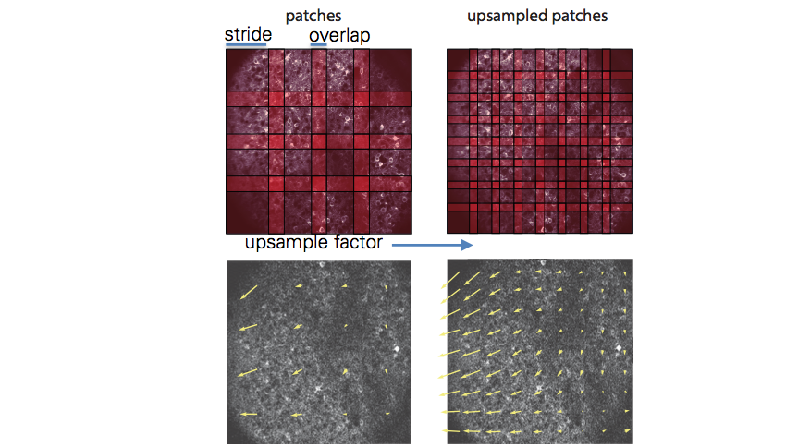

more info : (Eftychios A. Pnevmatikakis, Andrea Giovannucci, NormCorre)[*http://biorxiv.org/content/biorxiv/early/2017/02/14/108514.full.pdf*](http://biorxiv.org/content/biorxiv/early/2017/02/14/108514.full.pdf)

% 'd1','d2': size FOV movie
% 'grid_size','overlap_pre': parameters regulating size of patch (size patch ~ (grid_size + 2*overlap_pre))
% 'mot_uf': upsampling factor of the grid for shift application
% 'bin_width': how often to update the template
% 'max_shift': maximum allowed rigid shift
% 'max_dev': maximum deviation allowed for each patch from the rigid shift value
options_nr = NoRMCorreSetParms('d1',size(Y,1),'d2',size(Y,2),...
                    'grid_size',[48,48],'mot_uf',4,'overlap_pre',[16,16],...
                    'bin_width',100,'max_shift',15,'max_dev',8);
[M_nr,shifts_nr,template_nr] = normcorre_batch(Y,options_nr,template_rg); 

## view data

M_nrs = downsample_data(M_nr,'time',tsub);
play_movie({Y_sub,M_rgs,M_nrs},{'raw data','rigid','pw-rigid'},minY,maxY);

# Assessing Motion correction Quality for the raw, rigid corrected and piecewise rigid corrected videos

for motion correction quality assessment

## using smoothness *(mean over time)*

## using correlation to the template *(Pearson Correlation coefficient)*

see : [http://docs.opencv.org/2.4/doc/tutorials/imgproc/histograms/template_matching/template_matching.html](http://docs.opencv.org/2.4/doc/tutorials/imgproc/histograms/template_matching/template_matching.html) ( like a normalized SSD )

## optical flow :

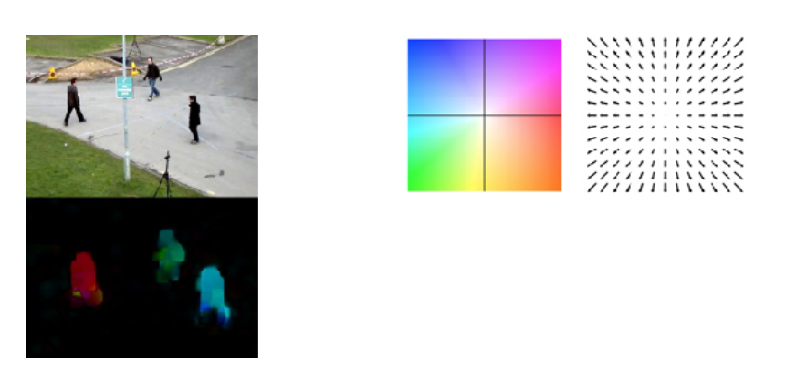

more info : [*http://docs.opencv.org/trunk/d7/d8b/tutorial_py_lucas_kanade.html*](http://docs.opencv.org/trunk/d7/d8b/tutorial_py_lucas_kanade.html)

[cY,mY,vY] = motion_metrics(Y,options_rg.max_shift);
[cM_rg,mM_rg,vM_rg] = motion_metrics(M_rg,options_rg.max_shift);
[cM_nr,mM_nr,vM_nr] = motion_metrics(M_nr,options_rg.max_shift);

## plottings

figure;
    ax(1) = subplot(2,3,1); imagesc(mY,[minY,maxY]);          axis equal; axis tight; axis off; title('mean raw data','fontsize',14,'fontweight','bold')
    ax(2) = subplot(2,3,2); imagesc(mM_rg,[minY,maxY]);       axis equal; axis tight; axis off; title('mean rigid corrected','fontsize',14,'fontweight','bold')
    ax(3) = subplot(2,3,3); imagesc(mM_nr,[minY,maxY]);       axis equal; axis tight; axis off; title('mean non-rigid corrected','fontsize',14,'fontweight','bold')
    
    subplot(2,3,4); 
        plot(1:T,cY,1:T,cM_rg,1:T,cM_nr); 
            legend('raw data','rigid','non-rigid');           title('correlation coefficients','fontsize',14,'fontweight','bold')
    subplot(2,3,5); 
        scatter(cY,cM_rg); hold on; 
        plot([0.9*min(cY),1.05*max(cM_rg)],[0.9*min(cY),1.05*max(cM_rg)],'--r'); 
        axis square;
        xlabel('raw data','fontsize',14,'fontweight','bold'); ylabel('rigid corrected','fontsize',14,'fontweight','bold');
    subplot(2,3,6); 
        scatter(cM_rg,cM_nr); hold on; 
        plot([0.95*min(cM_rg),1.05*max(cM_nr)],[0.95*min(cM_rg),1.05*max(cM_nr)],'--r'); 
        axis square;
        xlabel('rigid corrected','fontsize',14,'fontweight','bold'); ylabel('non-rigid corrected','fontsize',14,'fontweight','bold');
    linkaxes(ax,'xy')

# CNMF on patches 

This method builds upon and extends (Pnevmatikakis et al, Neuron, 2016) [*http://www.cell.com/neuron/fulltext/S0896-6273(15)01084-3*](http://www.cell.com/neuron/fulltext/S0896-6273(15)01084-3)

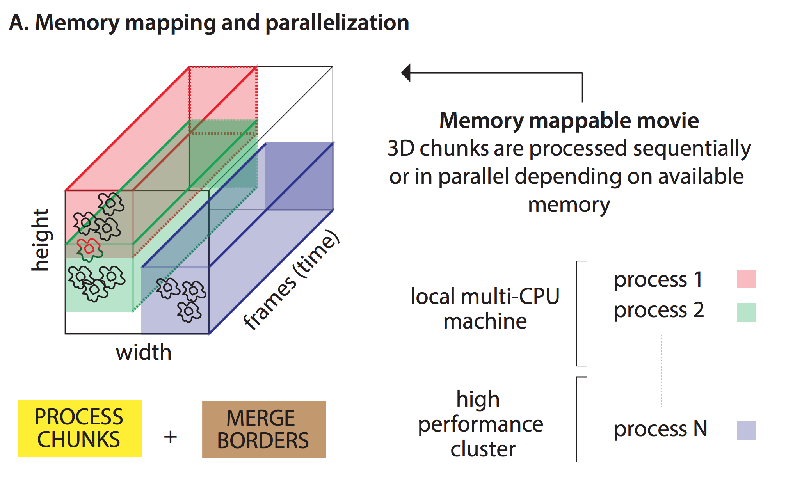

            We run portion of the CNMF algorithm on patches

            We merge the patches with special attention to neurons on the border.

            We refine the result by rerunning CNMF on the whole movie

sizY = size(M_nr);
patch_size = [30,30];                   % size of each patch along each dimension (optional, default: [32,32])
overlap = [8,8];                        % amount of overlap in each dimension (optional, default: [4,4])

patches = construct_patches(sizY(1:end-1),patch_size,overlap);
K = 4;                      % number of components to be found
tau = 4;                    % std of gaussian kernel (half size of neuron) 
p = 0;                      % order of autoregressive system (p = 0 no dynamics, p=1 just decay, p = 2, both rise and decay)

## Creating an option object for passing parameters more easily

options = CNMFSetParms(...
    'd1',sizY(1),'d2',sizY(2),...
    'temporal_iter',2,...                 % number of block-coordinate descent steps 
    'ssub',1,...                          % downsample in space
    'tsub',2,...                          % downsample in time
    'merge_thr',0.8,...                   % merging threshold
    'gSig',tau,... 
    'gnb',2,...                           % number of background components
    'spatial_method','regularized'...
    );

# run CNMF algorithm

Two parts :

- updating spatially

- updating temporally

And then compbine the Patches together

tic;
[A,b,C,f,S,P,RESULTS,YrA] = run_CNMF_patches(M_nr,K,patches,tau,p,options);
toc

## Here is a simple GUI

to view the modification

Cn = correlation_image_max(M_nr);
Coor = plot_contours(A,Cn,options,1); close;
run_GUI = false;
if run_GUI
    GUIout = ROI_GUI(A,options,Cn,Coor,keep,ROIvars);   
    options = GUIout{2};
    keep = GUIout{3};    
end

# DISCARD LOW QUALITY COMPONENT ¶

## The patch dubdivision creates several spurious components that are not neurons

We select the components according to criteria examining spatial and temporal components

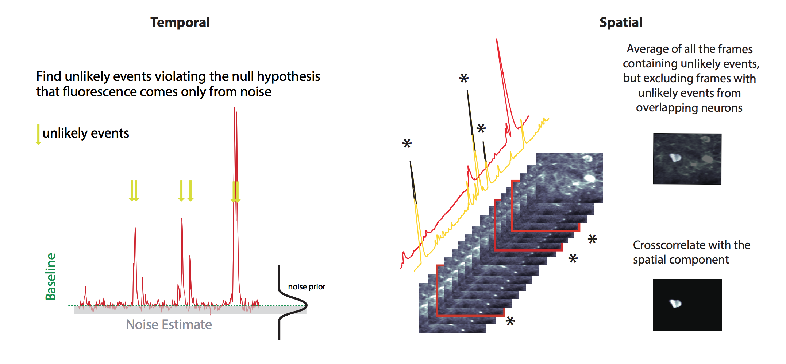

Temporal components, for each trace:

- compute the robust mode, corresponding to the baseline value

- use the values under the mode to estimate noise variance

- compute the probability of having large transients given the noise distribution estimated

- Threshold on this probability s.t. some of the component are discarded because lacking large enough positive transients

Spatial components, for each components:

- average the frames in the moveie where the neurons is active (from temporal component), this provides a nice image of the neuron

- compare this image with the corresponding spatial component (Person's correlation coefficient)

- threshold the correlation coefficient

[ROIvars.rval_space,ROIvars.rval_time,ROIvars.max_pr,ROIvars.sizeA,keep] = classify_components(M_nr,A,C,b,f,YrA,options);

# Rejected vs Selected components

throw = ~keep;
figure;
    ax1 = subplot(121); plot_contours(A(:,keep),Cn,options,0,[],Coor,1,find(keep)); title('Selected components','fontweight','bold','fontsize',14);
    ax2 = subplot(122); plot_contours(A(:,throw),Cn,options,0,[],Coor,1,find(throw));title('Rejected components','fontweight','bold','fontsize',14);
    linkaxes([ax1,ax2],'xy')

## Inspecting more the components

plot_components_GUI(M_nr,A(:,keep),C(keep,:),b,f,Cn,options);

# refine the temporal part of the CNMF

## by re-doing an update_temporal on the selected components

A_keep = A(:,keep);
C_keep = C(keep,:);
[C2,f2,P2,S2,YrA2] = update_temporal_components(reshape(M_nr,[],T),A_keep,b,C_keep,f,P,options);

# Extract DF/F values 

(optional)

## DF/F is  a ratio of the signal over the background. 

It is a way of normalizing the calcium traces signal against the high variability of its detected signal. Mainly due to modification in laser intensity, protein absorbtion ... 

Those modifications will create  different min and max values  as well as as a low temporal variation of the signal. 

It will allow us to make a right comparison of the signal over time and over different neurons.

More information [here](https://github.com/epnev/ca_source_extraction/docs/notes/DF_F_note.pdf) 

df_percentile = 30;
window = 1000; 

F = diag(sum(A_keep.^2))*(C2 + YrA2);                       % fluorescence
Fd = prctfilt(F,df_percentile,window);                      % detrended fluorescence
Bc = prctfilt((A_keep'*b)*f2,30,1000,300,0) + (F-Fd);       % background + baseline for each component
F_dff = Fd./Bc;

# Deconvolve data

- To infer the true shape of the calcium traces using an autoregressive framework

- To infer the most likely spike train ( also called particular events). It will find the probability of a spike train according to the mean and std of the trace.

- If it is superior to a threshold it will be defined as a particular event/neural spike

- This will give us a matrix which is itself constrained ( C from CNMF )

learn more : (Friedrich & al) [http://journals.plos.org/ploscompbiol/article?id=10.1371/journal.pcbi.1005423](http://journals.plos.org/ploscompbiol/article?id=10.1371/journal.pcbi.1005423) see the demo here : [https://github.com/j-friedrich/OASIS/blob/master/examples/Demo.ipynb](https://github.com/j-friedrich/OASIS/blob/master/examples/Demo.ipynb)

nNeurons = size(F_dff,1);
C_dec = zeros(size(F_dff));
S = zeros(size(F_dff));
kernels = cell(nNeurons,1);
min_sp = 3;    % find spikes resulting in transients above min_sp x noise level

for i = 1:nNeurons
    [C_dec(i,:),S(i,:),kernels{i}] = deconvCa(F_dff(i,:), [], min_sp, true, false, [], 20, [], 0);
end

# plot a random component

i = randi(nNeurons);

figure;plot(1:T,F_dff(i,:),'--k'); hold all; plot(1:T,C_dec(i,:),'r','linewidth',2);
    spt = find(S(i,:));
    if spt(1) == 1; spt(1) = []; end
    hold on; scatter(spt,repmat(-0.25,1,length(spt)),'m*')
    title(['Component ',num2str(i)]);
    
    legend('Fluorescence DF/F','Deconvolved','Spikes')